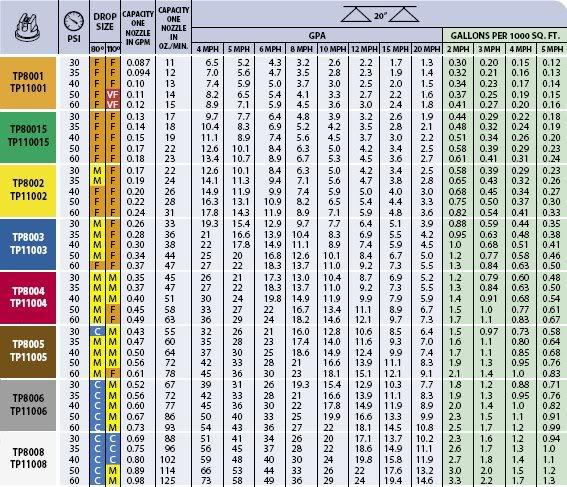

Parameterization of spray nozzle per table above

numberNozzles = 50;
pressureDrop = [0, 30, 35, 40, 50, 60]; % psi
volFlowRate =  [0, .087, .094, .10, .11, .12]*10*numberNozzles; % gpm

Maximum displacement of the needle valve

d_0 = 5e-3*40;
theta = pi/2;
h_MAX = d_0 * (1 - (1-cos(theta/2)))/sin(theta)*40

h_MAX = 5.6569

Define experimental pressure vs. duty cycle

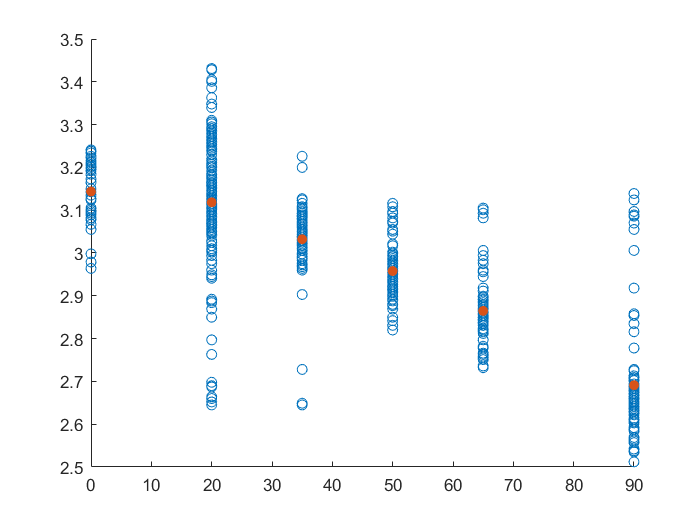

clf
load('modelTestStand03.mat');
DC_brkpts = [0, 20, 35, 50, 65, 90];
for i=1:length(DC_brkpts)
    p(i) = mean(modelTest03.y(modelTest03.u==DC_brkpts(i)));
end
scatter(modelTest03.u,modelTest03.y)
hold on
scatter(DC_brkpts,p,'filled')
hold off

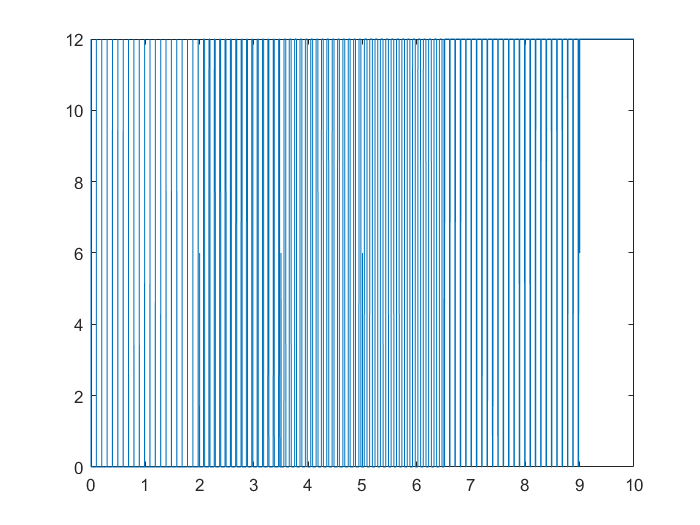

tf = 10;
ts = 1e-3;
DC = 50;
t = (0:.001:tf)';
f = zeros(size(t));
c1 = t<2;
f(c1) = square(2*100*t(c1)/pi,1);
c2 = t>2 & t<3.5;
f(c2) = square(2*100*t(c2)/pi,20);
c3 = t>3.5 & t<5;
f(c3) = square(2*100*t(c3)/pi,35);
c4 = t>5 & t<6.5;
f(c4) = square(2*100*t(c4)/pi,50);
c5 = t>6.5 & t<9;
f(c5) = square(2*100*t(c5)/pi,90);
c6 = t>9;
f(c6) = square(2*100*t(c6)/pi,100);
f = 12 * (f+1)/2;

plot(t,f)

%p_fit = fit(DC_brkpts'/10,p','smoothingspline');
%p_exp = p_fit(t);